clc;close all;clear all;
load("data\system_parameters.mat");
addpath('inc\')

## Discrete Path

load("data\trajectory_jointSpace_discrete.mat")
for i = 1:length(q)
    T = fwdKin(q(:,i),p);
    o4 = T.T40(1:3,4);
    condNum(i) = cond(jac(o4,T));
end

hold on
plot(0:2*pi/36:2*pi,condNum,'DisplayName',"Discrete Trajectory");

## 10 knot trajectory

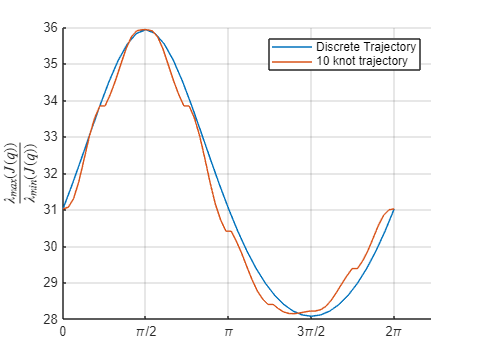

load("data\trajectory_jointSpace_10points.mat")
q = qAB_10;
for i = 1:length(q)
    T = fwdKin(q(:,i),p);
    o4 = T.T40(1:3,4);
    condNum(i) = cond(jac(o4,T));
end
plot(0:2*pi/(length(q)-1):2*pi,condNum,'DisplayName',"10 knot trajectory")
xticks([0 pi/2 pi 3*pi/2 2*pi])
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi'})
ylabel("$\frac{\lambda_{max}(J(q))}{\lambda_{min}(J(q))}$",'Interpreter','latex')
legend
grid on